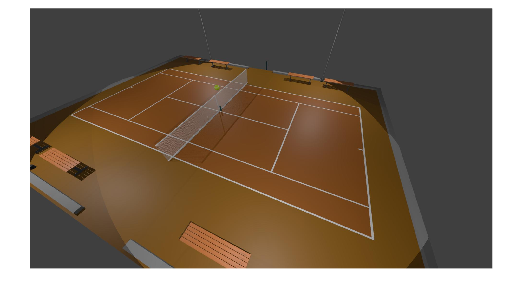

imagePath = "captures\leftImg_1.jpeg";
% Read the image from the specified path
img = imread(imagePath);
imshow(img);

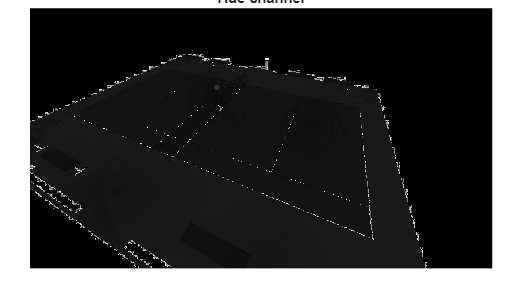


hsvImg = rgb2hsv(img);
H = hsvImg(:, :, 1); imshow(H); title('Hue channel'); 

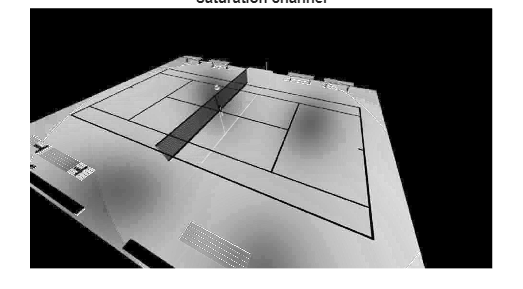

S = hsvImg(:, :, 2); imshow(S); title('Saturation channel');

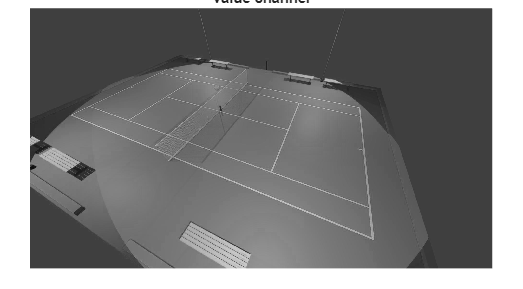

V = hsvImg(:, :, 3); imshow(V); title('Value channel');

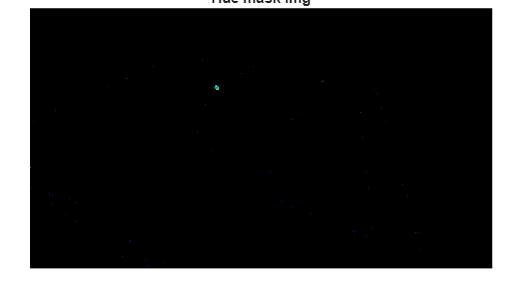


hueMask = (H > 0.18 & H < 0.20);
satMask = (S > 0 & S < 1);
valMask = (V > 0 & V < 1);

hueMaskImg = hsvImg;
hueMaskImg(repmat(~hueMask, [1 1 3])) = 0;
imshow(hueMaskImg); title('Hue mask img');

    
% ---- Keep ONLY top-right region ----
[H, W] = size(hueMaskImg);

rowCut = round(0.70 * H);   % top 50%
colCut = round(0.01 * W);   % right 30% (tune this)

% mask starts as all FALSE (masked out)
mask = false(H, W);
mask(1:rowCut, colCut:W) = true;

imgCut = hueMaskImg;
imgCut(~mask) = 0;

imshow(imgCut)